## Example 1: Window Functions


% Define window length and number of samples for fft
M = 64; % Choose an appropriate window length
n = -M/2 : M/2 - 1;
NFFT = 1024;

% Window functions
hanning_window = hanning(M);
hamming_window = hamming(M);
blackman_window = blackman(M);
blackmanharris_window = blackmanharris(M);
chebwin_window = chebwin(M, 30); % 30 dB sidelobe attenuation, you can adjust

% Plot the frequency response of each window
figure;

% Time domain representation subplot
subplot(2, 1, 1);
plot(n, hanning_window, n, hamming_window, n, blackman_window, n, blackmanharris_window, n, chebwin_window);
title('Time Domain Representation of Window Functions');
xlabel('Sample');
ylabel('Amplitude');
legend('Hanning', 'Hamming', 'Blackman', 'Blackman-Harris', 'Chebwin');
grid on;

% Frequency response subplot
subplot(2, 1, 2);

% Hanning window
X1 = fftshift(fft(hanning_window, NFFT));
Freq = (-NFFT/2 : NFFT/2 - 1) / NFFT;
Y1 = X1(1 : length(Freq)) / max(abs(X1));
mag_dB = 10 * log10(Y1);
plot(Freq, mag_dB, 'DisplayName', 'Hanning');

hold on;

% Hamming window
X2 = fftshift(fft(hamming_window, NFFT));
Y2 = X2(1 : length(Freq)) / max(abs(X2));
mag_dB2 = 10 * log10(Y2);
plot(Freq, mag_dB2, 'DisplayName', 'Hamming');


% Blackman window
X3 = fftshift(fft(blackman_window, NFFT));
Y3 = X3(1 : length(Freq)) / max(abs(X3));
mag_dB3 = 10 * log10(Y3);
plot(Freq, mag_dB3, 'DisplayName', 'Blackman');


% Blackman-Harris window
X4 = fftshift(fft(blackmanharris_window, NFFT));
Y4 = X4(1 : length(Freq)) / max(abs(X4));
mag_dB4 = 10 * log10(Y4);
plot(Freq, mag_dB4, 'DisplayName', 'Blackman-Harris');


% Chebwin window
X5 = fftshift(fft(chebwin_window, NFFT));
Y5 = X5(1 : length(Freq)) / max(abs(X5));
mag_dB5 = 10 * log10(Y5);
plot(Freq, mag_dB5, 'DisplayName', 'Chebwin');

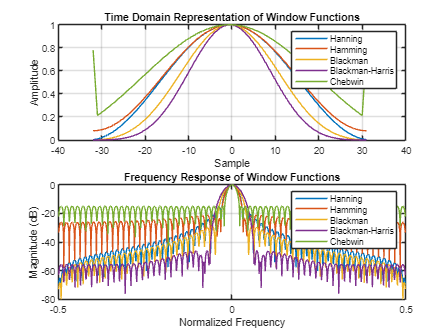


title('Frequency Response of Window Functions');
xlabel('Normalized Frequency');
ylabel('Magnitude (dB)');
legend('show');
grid on;
hold off;

## Example 2: Short-Time Fourier Transform ANALYSIS

clc
clear

% (a) Reading and resampling an audio file
filename = 'speechfiles/bbaq7a.wav'; 
[y, originalFs] = audioread(filename);
sound(y,originalFs)

resample to 16kHz

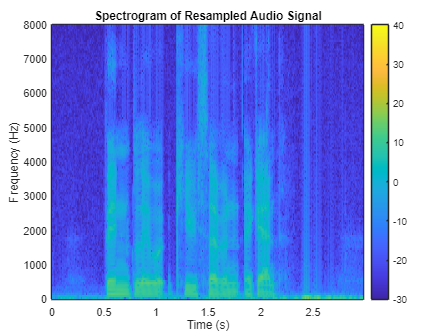

targetFs = 16000; % Target sampling rate 
% originalFs = 25000 % original sampling rate
y_resampled = resample(y, targetFs, originalFs);
% The resample function in MATLAB is used to change the sample rate of a signal. It is used to upsample or downsample audio signals. 

% (c) Analyzing the Time-Frequency representation
% Choose appropriate parameters
windowSize = 256;
overlapFactor = 0.5;
hammingWindow = hamming(windowSize);

% Apply STFT to the resampled signal
[X_stft, timeVector, freqVector] = stft_ece(y_resampled, hammingWindow, overlapFactor, targetFs);

% Plot the spectrogram
figure;
pl = pcolor(timeVector, freqVector, 10 * log10(abs(X_stft)));
set(pl, 'EdgeColor', 'none');
clim([-30, 40]);
title('Spectrogram of Resampled Audio Signal');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
ylim([0 targetFs/2]);
colorbar;

% (Optional) Play the resampled audio
sound(y_resampled, targetFs);


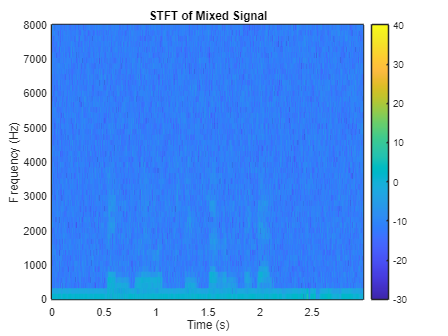

run_stft

## Example 3: Short-Time Fourier Transform SYNTHESIS

clc
clear

% readfile 
filename = 'speechfiles/bbaq7a.wav'; 
[y, originalFs] = audioread(filename);

%resample
targetFs = 16000;
y_resampled = resample(y, targetFs, originalFs);

% stft factors
windowSize = 256;
hammingWindow = hamming(windowSize);
overlapFactor = 0.5;

% stft
[X_stft, timeVector, freqVector] = stft_ece(y_resampled, hammingWindow, overlapFactor, targetFs);

% Inverse Stft
[x_ifft] = istft_ece(X_stft, hammingWindow, overlapFactor);

% Play sound
sound(x_ifft,targetFs)